set(0,'DefaultAxesFontName', 'Times New Roman')
set(0,'DefaultAxesFontSize', 28)
set(0,'defaultaxeslinewidth',2)
set(0,'defaultpatchlinewidth',1)
set(0,'defaultlinelinewidth',3)
set(0,'defaultTextInterpreter','latex')

%%% Plot time progression for 6.1.1
K=100;
[x,y] = Simulations_1DMix(0,1,4,K,0,1e-4);

Elapsed time is 0.329170 seconds.


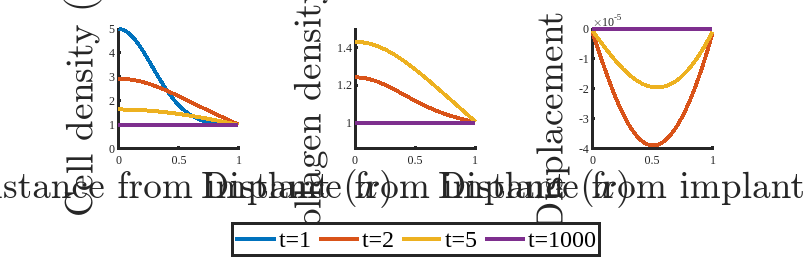

times = [1 2 5 1000];

figure('Units','normalized','Position',[0 0 0.85 0.5])
tiledlayout(1,3)
nexttile(1);
ylim([0,5])
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Cell density $(n)$','FontSize',28)
axis square
nexttile(2);
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Collagen density $(\rho)$','FontSize',28)
ylim([0.86,1.5])
axis square
nexttile(3);
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Displacement $(u)$','FontSize',28)
% ylim([-1e-3,1e-3]) 
axis square

for i=1:length(times)
    n = [y(1:K,times(i))];
    p = [y(K+1:2*K,times(i))];
    u = [y(2*K+1:3*K,times(i))];

    ax1 = nexttile(1);
    hold(ax1,"on")
    plot(x,n,'LineWidth',3)

    ax2 = nexttile(2);
    hold(ax2,"on")
    plot(x,p,'LineWidth',3)
    
    ax3 = nexttile(3);
    hold(ax3,"on")
    plot(x,u,'LineWidth',3)    
end

leg = legend('Orientation', 'Horizontal');
leg.Layout.Tile = 'south';
legend('t=1', 't=2', 't=5', 't=1000','FontSize',18);
saveas(gcf,'v01-02.png');

%%% Plot time progression for v11
K=100;
[x,y] = Simulations_1DMix(1,1,0,K,0,1);

Elapsed time is 0.272312 seconds.


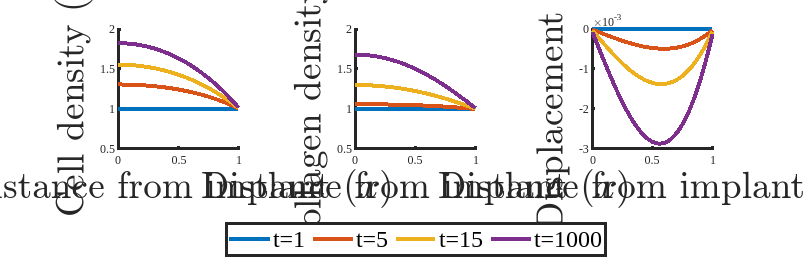

times = [1 5 15 1000];

figure('Units','normalized','Position',[0 0 0.85 0.5])
tiledlayout(1,3)
nexttile(1);
ylim([0.5,2])
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Cell density $(n)$','FontSize',28)
axis square
nexttile(2);
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Collagen density $(\rho)$','FontSize',28)
ylim([0.5,2])
axis square
nexttile(3);
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Displacement $(u)$','FontSize',28)
% ylim([-1e-3,1e-3]) 
axis square

for i=1:length(times)
    n = [y(1:K,times(i))];
    p = [y(K+1:2*K,times(i))];
    u = [y(2*K+1:3*K,times(i))];

    ax1 = nexttile(1);
    hold(ax1,"on")
    plot(x,n,'LineWidth',3)

    ax2 = nexttile(2);
    hold(ax2,"on")
    plot(x,p,'LineWidth',3)
    
    ax3 = nexttile(3);
    hold(ax3,"on")
    plot(x,u,'LineWidth',3)    
end

leg = legend('Orientation', 'Horizontal');
leg.Layout.Tile = 'south';
legend('t=1', 't=5', 't=15', 't=1000','FontSize',18);
saveas(gcf,'v11_time.png');

%%% plot v11 end profile
K = 100;
taup1list = [1e-3 0.3 0.7 1]; %% max 1

figure('Units','normalized','Position',[0 0 0.85 0.5])
tiledlayout(1,3)
nexttile(1);
ylim([0.9,2])
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Cell density $(n)$','FontSize',28)
axis square
nexttile(2);
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Collagen density $(\rho)$','FontSize',28)
ylim([0.9,2])
axis square
nexttile(3);
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Displacement $(u)$','FontSize',28)
% ylim([-1e-3,1e-3]) 
axis square

for i=1:length(taup1list)
    [x,y] = Simulations_1DMix(1,1,0,K,0,taup1list(i));
    n = [y(1:K,end)];
    p = [y(K+1:2*K,end)];
    u = [y(2*K+1:3*K,end)];
    
    ax1 = nexttile(1);
    hold(ax1,"on")
    plot(x,n,'LineWidth',3)
    
    ax2 = nexttile(2);
    hold(ax2,"on")
    plot(x,p,'LineWidth',3)

    ax3 = nexttile(3);
    hold(ax3,"on")
    plot(x,u,'LineWidth',3) 
end

Elapsed time is 0.132919 seconds.
Elapsed time is 0.149627 seconds.
Elapsed time is 0.144915 seconds.
Elapsed time is 0.264934 seconds.


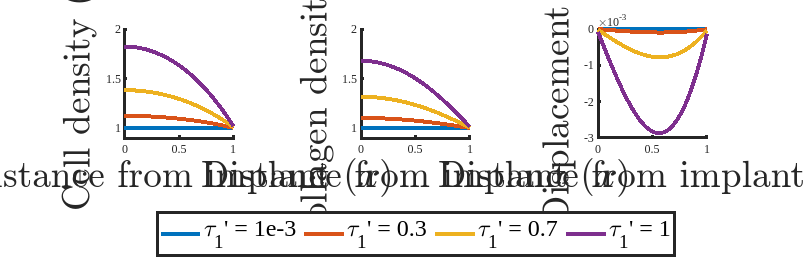


leg = legend('Orientation', 'Horizontal');
leg.Layout.Tile = 'south';
legend('\tau_1'' = 1e-3', '\tau_1'' = 0.3', '\tau_1'' = 0.7', '\tau_1'' = 1','FontSize',18);
saveas(gcf,'v11.png');

%%% plot v12 end profile
K = 100;
taup2list = [0.1 2 5 8]; %% max value is 8

figure('Units','normalized','Position',[0 0 0.85 0.5])
tiledlayout(1,3)
nexttile(1);
ylim([0.9,1.2])
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Cell density $(n)$','FontSize',28)
axis square
nexttile(2);
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Collagen density $(\rho)$','FontSize',28)
ylim([0.9,1.2])
axis square
nexttile(3);
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Displacement $(u)$','FontSize',28)
% ylim([-1e-3,1e-3]) 
axis square

for i=1:length(taup2list)
    [x,y] = Simulations_1DMix(1,2,0,K,0,taup2list(i));
    n = [y(1:K,end)];
    p = [y(K+1:2*K,end)];
    u = [y(2*K+1:3*K,end)];
    
    ax1 = nexttile(1);
    hold(ax1,"on")
    plot(x,n,'LineWidth',3)
    
    ax2 = nexttile(2);
    hold(ax2,"on")
    plot(x,p,'LineWidth',3)

    ax3 = nexttile(3);
    hold(ax3,"on")
    plot(x,u,'LineWidth',3) 
end

Elapsed time is 0.139932 seconds.
Elapsed time is 0.133561 seconds.
Elapsed time is 0.137881 seconds.
Elapsed time is 0.263637 seconds.


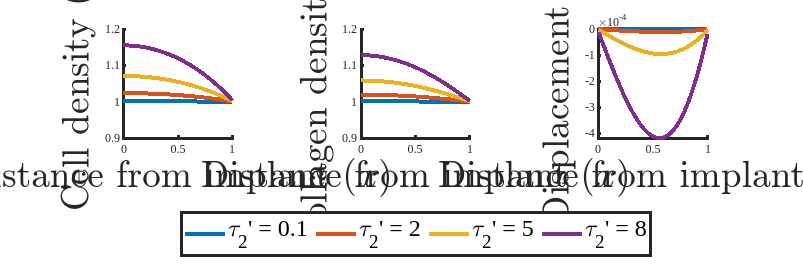


leg = legend('Orientation', 'Horizontal');
leg.Layout.Tile = 'south';
legend('\tau_2'' = 0.1', '\tau_2'' = 2', '\tau_2'' = 5', '\tau_2'' = 8','FontSize',18);
saveas(gcf,'v12.png');

%%% plot v21 with different a values
K = 100;
alist = [1 2 3 4 5];

figure('Units','normalized','Position',[0 0 0.85 0.5])
tiledlayout(1,3)
nexttile(1);
ylim([0.5,3])
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Cell density $(n)$','FontSize',28)
axis square
nexttile(2);
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Collagen density $(\rho)$','FontSize',28)
ylim([0.5,3])
axis square
nexttile(3);
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Displacement $(u)$','FontSize',28)
% ylim([-1e-3,1e-3]) 
axis square

for i=1:length(alist)
    [x,y] = Simulations_1DMix(2,1,0,K,alist(i),0.7);
    n = [y(1:K,end)];
    p = [y(K+1:2*K,end)];
    u = [y(2*K+1:3*K,end)];
    
    ax1 = nexttile(1);
    hold(ax1,"on")
    plot(x,n,'LineWidth',3)
    
    ax2 = nexttile(2);
    hold(ax2,"on")
    plot(x,p,'LineWidth',3)

    ax3 = nexttile(3);
    hold(ax3,"on")
    plot(x,u,'LineWidth',3) 
end

Elapsed time is 0.156624 seconds.
Elapsed time is 0.340590 seconds.
Elapsed time is 0.352404 seconds.
Elapsed time is 0.419853 seconds.
Elapsed time is 0.314060 seconds.


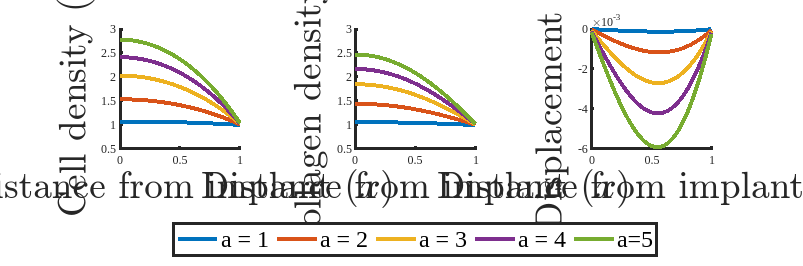


leg = legend('Orientation', 'Horizontal');
leg.Layout.Tile = 'south';
legend('a = 1', 'a = 2', 'a = 3', 'a = 4', 'a=5','FontSize',18);
saveas(gcf,'v21.png');

%%% plot v22 healthy and pathological result patients
K = 100;
tlist = [1 100];
[x1,y1] = Simulations_1DMix(2,2,4,K,1,1);

Elapsed time is 0.775698 seconds.


[x2,y2] = Simulations_1DMix(2,2,0,K,5,20);

Elapsed time is 0.519886 seconds.


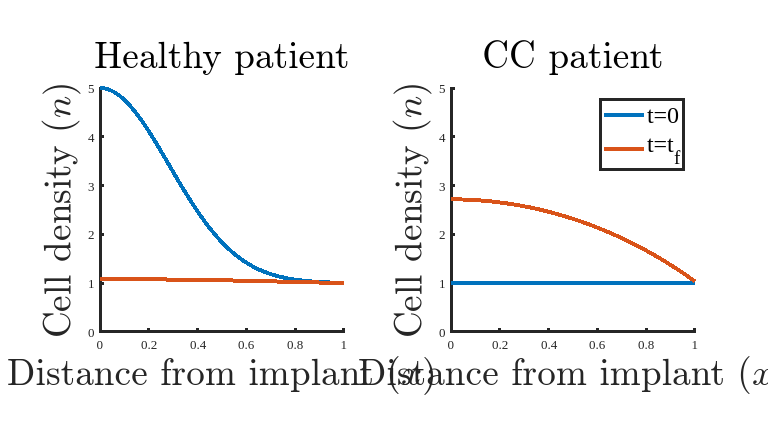


figure('Units','normalized','Position',[0 0 0.4 0.4])
tiledlayout(1,2)
nexttile(1);
title('Healthy patient','FontSize',28)
ylim([0,5])
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Cell density $(n)$','FontSize',28)
axis square
nexttile(2);
title('CC patient','FontSize',28)
ylim([0,5])
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Cell density $(n)$','FontSize',28)
axis square

for i=1:length(tlist)
    n1 = [y1(1:K,i)];
    n2 = [y2(1:K,i)];
    
    ax1 = nexttile(1);
    hold(ax1,"on")
    plot(x1,n1,'LineWidth',3)
    
    ax2 = nexttile(2);
    hold(ax2,"on")
    plot(x2,n2,'LineWidth',3)
end

legend('t=0', 't=t_f','FontSize',18);
saveas(gcf,'v22.png');

%%% plot v22 bistable case
K = 100;
tlist = [1 100];
[x1,y1] = Simulations_1DMix(2,2,1,K,4,5);

Elapsed time is 0.476642 seconds.


[x2,y2] = Simulations_1DMix(2,2,1.2,K,4,5);

Elapsed time is 0.647523 seconds.


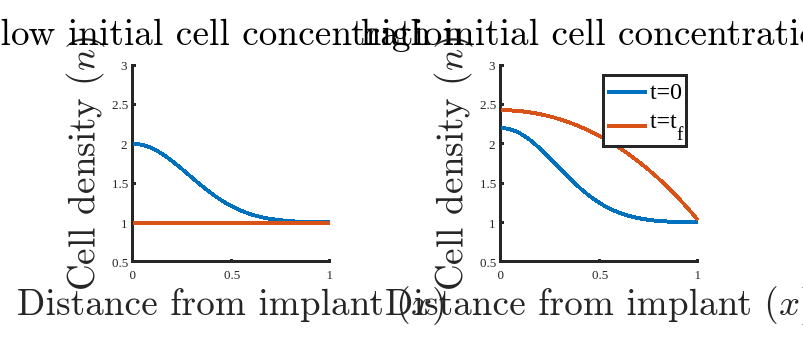


figure('Units','normalized','Position',[0 0 0.8 0.6])
tiledlayout(1,2)
ax1 = nexttile(1);
title('low initial cell concentration','FontSize',28)
ylim([0.5,3])
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Cell density $(n)$','FontSize',28)
axis square
ax2 = nexttile(2);
title('high initial cell concentration','FontSize',28)
ylim([0.5,3])
xlabel('Distance from implant $(x)$','FontSize',28) 
ylabel('Cell density $(n)$','FontSize',28)
axis square

for i=1:length(tlist)
    n1 = [y1(1:K,tlist(i))];
    n2 = [y2(1:K,tlist(i))];
    
    ax1 = nexttile(1);
    hold(ax1,"on")
    plot(x1,n1,'LineWidth',3)
    
    ax2 = nexttile(2);
    hold(ax2,"on")
    plot(x2,n2,'LineWidth',3)
end

legend('t=0', 't=t_f','FontSize',18);
saveas(gcf,'v22_bistable.png');

%%% plot v22 bistable case time progression
K = 100;
tend = 50;
t = 0:tend-1;
ninit = [0 0.5 1 1.5 2 2.5];
n = zeros(tend,1);

figure('Units','normalized','Position',[0 0 0.3 0.5])
ylim([0.5,4])
xlabel('Time step, $i$','FontSize',32) 
ylabel('Cell density, $n(0,t)$','FontSize',32)
hold on

for trial=1:length(ninit)
    [~,y] = Simulations_1DMix(2,2,ninit(trial),K,4,5);
    for i=1:tend
        n(i) = y(1,i);
    end
    if n(end) > 1.1
        plot(t,n,"red", 'LineWidth',3)
    else
        plot(t,n,"blue", 'LineWidth',3)
    end
end

Elapsed time is 0.149146 seconds.
Elapsed time is 0.501814 seconds.
Elapsed time is 0.502857 seconds.
Elapsed time is 0.635286 seconds.


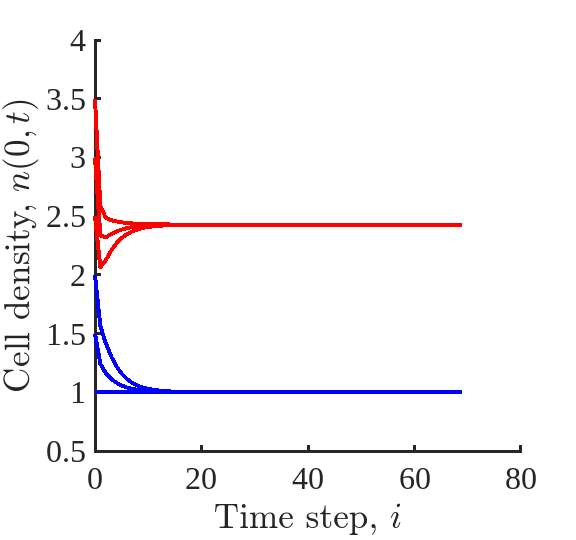


saveas(gcf,'v22_time_progression.png');

%%% Test anyting
K = 100;
[x,y] = Simulations_1DMix(2,2,0,K,1,19);

Elapsed time is 0.391257 seconds.
